# Actividad Práctica N°1. Representación de sistemas y control PID.

## Caso de estudio 2. Sistema de tres variables de estado.

### Consigna

Dadas las ecuaciones del motor de corriente continua con torque de carga $T_L$ no nulo, con los parámetros:

- 
$$L_{\textrm{AA}} =366\;{10}^{-6}$$


- 
$$J=5\;{10}^{-9}$$


- 
$$R_A =55\ldotp 6$$


- 
$$B_m =0$$


- 
$$K_i =6\ldotp 49\;{10}^{-3}$$


- 
$$K_m =6\ldotp 53\;{10}^{-3}$$


Modelado por las siguientes ecuaciones diferenciales:

- 
$$\frac{{\textrm{di}}_a \;}{\textrm{dt}}=\frac{-R_A }{\;L_{\textrm{AA}} }*i_a -\frac{\;K_m }{\;L_{\textrm{AA}} }\omega_r +\frac{1\;}{L_{\textrm{AA}} }v_a$$


- 
$$\frac{d\omega_r }{\textrm{dt}}=\frac{K_i \;}{J}i_a -\frac{B_m \;}{J}\omega {\;}_r -\frac{1\;}{J}T_L$$


- 
$$\frac{d\Theta_t }{\textrm{dt}}=\omega_r$$


Implementar un algoritmo de simulación para inferir el comportamiento de las variables interés  mediante integración Euler con $\Delta t={10}^{-7}$segundos para:

- Obtener el torque máximo que puede soportar el motor modelado mediante las ecuaciones diferenciales anteriores cuando se lo alimenta con $12V$, graficando para $5$ segundos de tiempo la velocidad angular y la corriente $i_a$.

- Mostrar simulaciones de 5 segundos que permitan observar la corriente $i_a$ en todo momento y establecer su valor máximo como para dimensionar dispositivos electrónicos.

- A partir de las curvas de mediciones de las variables graficadas, se requiere obtener el modelo del sistema considerando como entrada un escalón de $12V$, como salida a la velocidad angular, y a partir de $0\ldotp 1$ segundo se aplica un $T_L$ aproximado de $7\ldotp 5\;{10}^{-2} \;\textrm{Nm}$. En el archivo Curvas_Medidas_Motor.xls están las mediciones, en la primer hoja los valores y en la segunda los nombres. Se requiere obtener el modelo dinámico, para establecer las constantes de la corriente.

- Implementar un PID en tiempo discreto para que el ángulo del motor permanezca en una referencia de $1\;\textrm{rad}$. (Tip: a partir de $K_P =0\ldotp 1;K_i =0\ldotp 01;K_D =5$).

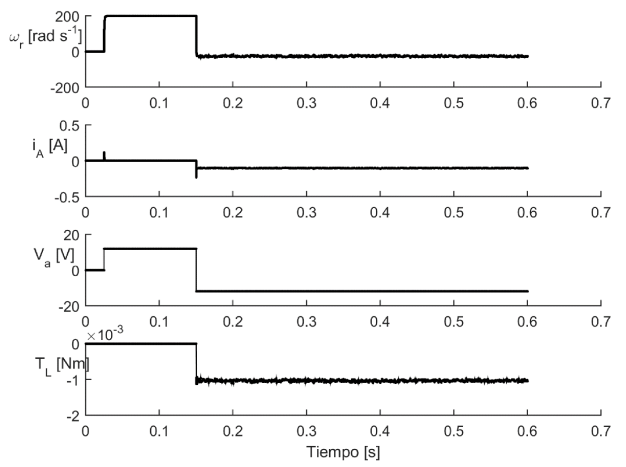

### Resolución

En primera instancia se integran las dos primeras ecuaciones diferenciales haciendo uso del método de Integración de Euler, con el paso fijado en la consigna del ejercicio.

Primero se pasiva la entrada que responde al torque del motor, para integrar las ecuaciones de velocidad angular y corriente en función de la entrada de tensión. Se aplica el teorema de superposición.

T = 0.6;
deltaT = 1e-7;
Kmax = T/deltaT;
t = linspace(0,T,Kmax);

Laa = 366e-6;
J = 5e-9;
Ra = 55.6;
Bm = 0;
Ki = 6.49e-3;
Km = 6.53e-3;

Vin = 12;
iaP = 0;
wrP = 0;
Ia = zeros(1, Kmax);
Wr = zeros(1, Kmax);
u = linspace(0, 0, Kmax);
Ia(1) = 0;
Wr(1) = 0;
u(1) = Vin;

A = [-Ra/Laa -Km/Laa; Ki/J -Bm/J];
B = [1/Laa; 0];
C1 = [1 0];
C2 = [0 1];

Ial(1) = 0;
Wrl(1) = 0;
x = [Ia(1) Wr(1)]';
Xop = [0 0]';

ii = 0;
for i = 1:(Kmax-1)
    ii = ii+deltaT;
    if(ii>=0 && ii<0.025)
        Vin = 0;
    end
    if(ii>=0.025 && ii<0.15)
        Vin = 12;
    end
    if(ii>=0.15)
        Vin = -12;
    end
    u(i) = Vin;
    iaP = -(Ra/Laa)*Ia(i)-(Km/Laa)*Wr(i)+(1/Laa)*u(i);
    wrP = (Ki/J)*Ia(i)-(Bm/J)*Wr(i);
    xP = A*(x-Xop)+B*u(i);
    x = x+xP*deltaT;
    Y1 = C1*x;
    Y2 = C2*x;
    Ial(i+1) = x(1);
    Wrl(i+1) = x(2);
end

A continuación, se grafican las dos salidas del sistema planteado para una entrada de tensión que inicia en $0V$, luego, al cabo de $0\ldotp 025\;\mathrm{seg}$ comienza a valer $12V$, para luego, a los $0\ldotp 125\;\mathrm{seg}$ cambiar su signo, pasando a valer $-12V$.

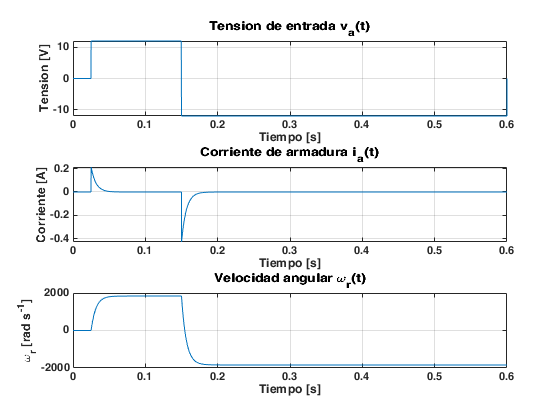

subplot(3,1,1);
plot(t,u,'LineWidth',3);
title('Tension de entrada v_a(t)');
xlabel('Tiempo [s]');
ylabel('Tension [V]');
grid;
subplot(3,1,2);
plot(t,Ial); 
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [s]');
ylabel('Corriente [A]')
grid;
subplot(3,1,3);
plot(t,Wrl); 
title('Velocidad angular \omega_r(t)');
xlabel('Tiempo [s]');
ylabel('\omega_r [rad s^{-1}]')
grid;

Las gráficas anteriores son para simplemente comparar resultados con las gráficas brindadas por la consigna. Ahora, para continuar con lo solicitado, se ingresará el escalón de tensión de $12\;V$ y se simulará el sistema durante $5\;\mathrm{seg}$.

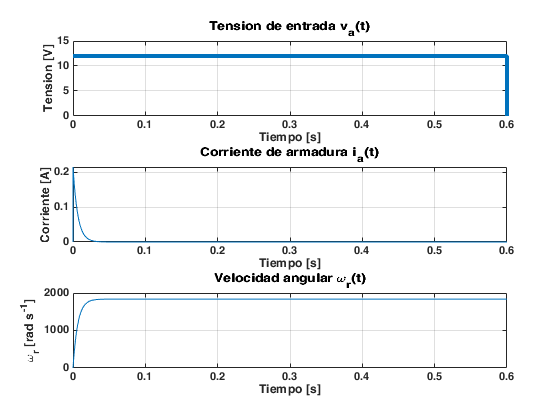

T = 0.6;
deltaT = 1e-7;
Kmax = T/deltaT;
t = linspace(0,T,Kmax);

Laa = 366e-6;
J = 5e-9;
Ra = 55.6;
Bm = 0;
Ki = 6.49e-3;
Km = 6.53e-3;

Vin = 12;
iaP = 0;
wrP = 0;
Ia = zeros(1, Kmax);
Wr = zeros(1, Kmax);
u = linspace(0, 0, Kmax);
Ia(1) = 0;
Wr(1) = 0;
u(1) = Vin;

A = [-Ra/Laa -Km/Laa; Ki/J -Bm/J];
B = [1/Laa; 0];
C1 = [1 0];
C2 = [0 1];

Ial(1) = 0;
Wrl(1) = 0;
x = [Ia(1) Wr(1)]';
Xop = [0 0]';

ii = 0;
for i = 1:(Kmax-1)
    ii = ii+deltaT;
    u(i) = Vin;
    iaP = -(Ra/Laa)*Ia(i)-(Km/Laa)*Wr(i)+(1/Laa)*u(i);
    wrP = (Ki/J)*Ia(i)-(Bm/J)*Wr(i);
    xP = A*(x-Xop)+B*u(i);
    x = x+xP*deltaT;
    Y1 = C1*x;
    Y2 = C2*x;
    Ial(i+1) = x(1);
    Wrl(i+1) = x(2);
end

subplot(3,1,1);
plot(t,u,'LineWidth',2);
title('Tension de entrada v_a(t)');
xlabel('Tiempo [s]');
ylabel('Tension [V]');
grid;
subplot(3,1,2);
plot(t,Ial,'LineWidth',2); 
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [s]');
ylabel('Corriente [A]')
grid;
subplot(3,1,3);
plot(t,Wrl,'LineWidth',2); 
title('Velocidad angular \omega_r(t)');
xlabel('Tiempo [s]');
ylabel('\omega_r [rad s^{-1}]')
grid;

Ahora, si a lo anterior, se le agregara la perturbación que representa el torque de carga, se podría modelar algo como lo siguiente:

T = 0.6;
deltaT = 1e-7;
Kmax = T/deltaT;
t = linspace(0,T,Kmax);

Laa = 366e-6;
J = 5e-9;
Ra = 55.6;
Bm = 0;
Ki = 6.49e-3;
Km = 6.53e-3;

Vin = 12;
TL = 0;
iaP = 0;
wrP = 0;
Ia = zeros(1, Kmax);
Wr = zeros(1, Kmax);
u = [linspace(0, 0, Kmax) linspace(0, 0, Kmax)];
Ia(1) = 0;
Wr(1) = 0;
u(1,1) = Vin;
u(1,2) = TL;

A = [-Ra/Laa -Km/Laa; Ki/J -Bm/J];
B = [1/Laa; -1/J];
C1 = [1 0];
C2 = [0 1];

Ial(1) = 0;
Wrl(1) = 0;
x = [Ia(1) Wr(1)]';
Xop = [0 0]';

ii = 0;
for i = 1:(Kmax-1)
    ii = ii+deltaT;
    if(ii>=0 && ii<0.025)
        Vin = 0;
        TL = 0;
    end
    if(ii>=0.025 && ii<0.15)
        Vin = 12;
        TL = 0;
    end
    if(ii>=0.15)
        Vin = -12;
        TL = 1.41e-3;
    end
    u(i,1) = Vin;
    u(i,2) = TL;
    iaP = -(Ra/Laa)*Ia(i)-(Km/Laa)*Wr(i)+(1/Laa)*u(i,1);
    wrP = (Ki/J)*Ia(i)-(Bm/J)*Wr(i)-(1/J)*u(i,2);
    xP = A*(x-Xop)+B.*u;
    x = x+xP*deltaT;
    Y1 = C1*x;
    Y2 = C2*x;
    Ial(i+1) = x(1);
    Wrl(i+1) = x(2);
end

subplot(4,1,1);
plot(t,Wrl); 
title('Velocidad angular \omega_r(t)');
xlabel('Tiempo [s]');
ylabel('\omega_r [rad s^{-1}]')
grid;
subplot(4,1,2);
plot(t,Ial); 
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [s]');
ylabel('Corriente [A]')
grid;
subplot(4,1,3);
plot(t,u(1));
title('Tension de entrada v_a(t)');
xlabel('Tiempo [s]');
ylabel('Tension [V]');
grid;
subplot(4,1,4);
plot(t,u(2));
title('Torque de carga T_L(t)');
xlabel('Tiempo [s]');
ylabel('Torque [Nm]');
grid;